# Tendencia

## ¿Qué es?

Tasa de cambio de la serie de tiempo. Usaremos la regresión lineal por ser la más simple.

clear all;
close all;
% enso = load("datos\data_nino.txt");
enso = readtable("datos\data_nino.txt");


disp(enso);

    x_YR    MON    NINO1_2    ANOM     NINO3    ANOM_1    NINO4    ANOM_2    NINO3_4    ANOM_3
    ____    ___    _______    _____    _____    ______    _____    ______    _______    ______

    1982     1      24.28     -0.24    25.84     0.17     28.01    -0.21      26.65      0.08 
    1982     2      25.38     -0.72    26.26    -0.11     27.99    -0.11      26.54      -0.2 
    1982     3      25.22     -1.38    26.92    -0.25     28.18    -0.05      27.09     -0.14 
    1982     4      24.57     -1.16    27.52    -0.05     28.61      0.1      27.83      0.02 
    1982     5         24     -0.62     27.7     0.49     29.19      0.4      28.37      


% Convertir la tabla a un timetable si no lo es
enso.Fecha = datetime(enso.x_YR, enso.MON, 1); % Asumiendo que 'x_YR' es el año y 'MON' es el mes

% promediosMensuales = groupsummary(enso, 'Fecha', 'month', 'mean', {'NINO1_2', 'NINO3', 'NINO4', 'NINO3_4'});

disp(enso)

    x_YR    MON    NINO1_2    ANOM     NINO3    ANOM_1    NINO4    ANOM_2    NINO3_4    ANOM_3       Fecha   
    ____    ___    _______    _____    _____    ______    _____    ______    _______    ______    ___________

    1982     1      24.28     -0.24    25.84     0.17     28.01    -0.21      26.65      0.08     01-Jan-1982
    1982     2      25.38     -0.72    26.26    -0.11     27.99    -0.11      26.54      -0.2     01-Feb-1982
    1982     3      25.22     -1.38    26.92    -0.25     28.18    -0.05      27.09     -0.14     01-Mar-1982
    1982     4      24.57     -1.16    27.52    -0.05     28.61      0.1   

Seguimos

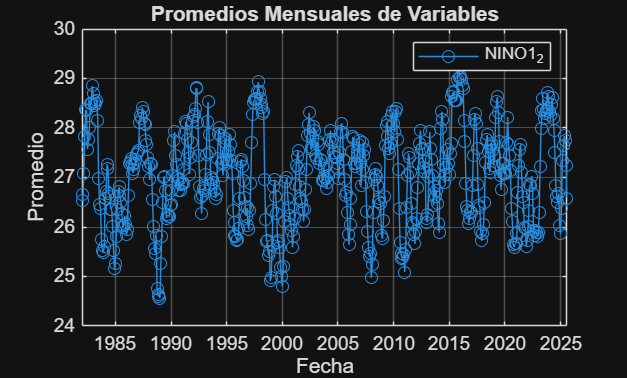

% Graficar los promedios mensuales
figure;
plot(enso.Fecha, enso.NINO3_4, '-o', 'DisplayName', 'NINO1_2');
% hold on;
% plot(enso.Fecha, enso.NINO3, '-o', 'DisplayName', 'NINO3');
% plot(enso.Fecha, enso.NINO4, '-o', 'DisplayName', 'NINO4');
% plot(enso.Fecha, enso.NINO3_4, '-o', 'DisplayName', 'NINO3_4');
% hold off;

% Añadir etiquetas y leyenda
xlabel('Fecha');
ylabel('Promedio');
title('Promedios Mensuales de Variables');
legend show;
grid on;

Ahora ajustamos a una regresion lineal

tiempo_num = datenum(enso.Fecha);

tiempo_num_2 = 1:length(enso.Fecha);


model_lineal = polyfit(tiempo_num, enso.NINO3_4, 1)

model_lineal =     0.0000   17.8344


model_lineal_2 = polyfit(tiempo_num_2, enso.NINO3_4, 1)

model_lineal_2 =     0.0004   26.9439




output_model_1 = polyval(model_lineal, tiempo_num);
output_model_2 = polyval(model_lineal_2, tiempo_num_2);

Graficamos

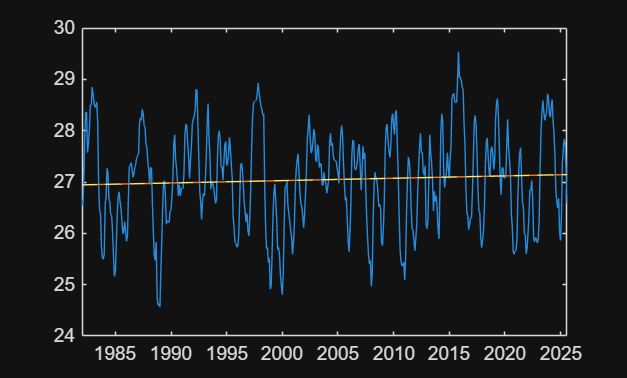

figure;
plot(enso.Fecha, enso.NINO3_4)
hold on;
plot(enso.Fecha, output_model_1)
hold on;
plot(enso.Fecha, output_model_2, '--', 'DisplayName', 'Modelo Lineal 2');
hold off;

Removiendo la tendencia

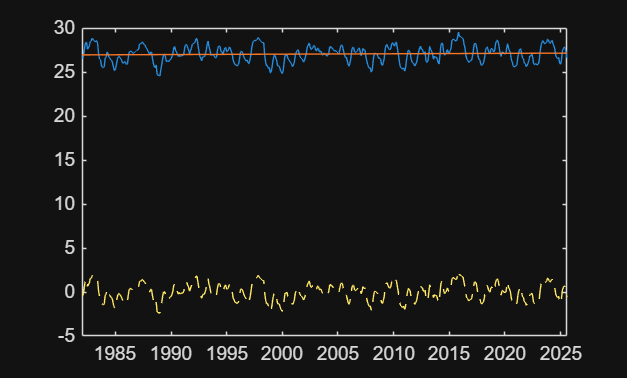


serie_sin_tendencia = enso.NINO3_4 - output_model_1;


figure;
plot(enso.Fecha, enso.NINO3_4)
hold on;
plot(enso.Fecha, output_model_1)
hold on;
plot(enso.Fecha, serie_sin_tendencia, '--', 'DisplayName', 'Serie sin Tendencia');
hold off;